# Sparse Bayesian logistic regression

## Model formulation

Given design matrix $X$ and response $y\in\{-1,1\}$, the indicator logistic regression model assumes  


$$P\left(y=1\right)=\sigma \left(X\Gamma \beta \right),$$


where $\Gamma = diag(\gamma_1,\cdots,\gamma_p), \beta = (\beta_1,\cdots,\beta_p)^T$. Here we introduce the latent indicator variable $\gamma_j$ who equals to 1 if $j$th variable $x_j$ is important and 0 if $x_j$ is unimportant.

To complete the Bayesian inference, it assumes $\beta_j\mid\alpha_j\sim N(0,\alpha_j^{-1})$, $\alpha_j\sim Gamma(a_0,b_0)$, $\gamma_j\sim Bernoulli(\rho)$, where $a_0,b_0,\rho$ are hyper-parameters. Generally speaking, $a_0,b_0$ can be set to $10^{-2},10^{-4}$ respectively, in the uninformative fashion. As for $\rho$, it controls the sparsity of the model and is tuned by BIC. Other parameters are inferred by variational Bayesian.

## Example

The following example shows how to apply this software. 

1.Consider a dataset with 30 features and 100 samples. Let 6 variables be important and takes value 2,1.5,1,-1,-1.5,2. 

p = 30;
n = 100;

beta = zeros(p, 1);
beta([1,6,11]) = [-2,-1.5,-1];
beta([16,21,26]) = [1,1.5,2];
inx = beta~=0;

X = mvnrnd(zeros(p,1),eye(p),n);
y = random('bino', 1, logsig(X*beta));
y(y==0) = -1;

2.Function `vbvs_logit` carries out the varitional Bayes inference and automatically select the optimal $\rho$ according to BIC. It admits parallel computing by by default. 

% Specific parameters
opt.maxiter = 100;
opt.a0 = 1e-2*ones(p,1);
opt.bo = 1e-4*ones(p,1);
opt.tol = 1e-4;
opt.intercept = false;
% Create parallel pool
% parpool;
model = vbvs_logit(X,y,opt);
model.rhomin

ans = 0.3669

Plot the posterior probability of $\gamma=1$ and estimates of $\beta$.

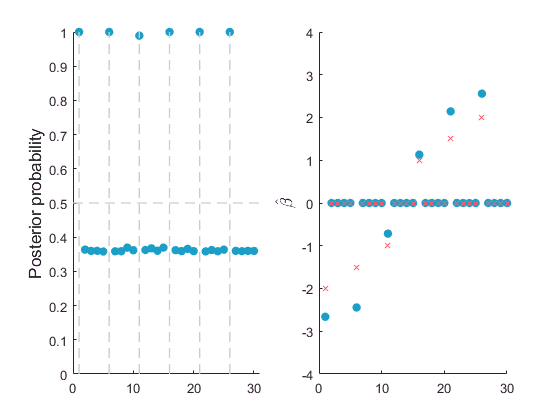

post = model.modelOPT.theta;
beta_hat = model.mu;
red = [1.0000    0.3686    0.4118];
blue = [0.1059    0.6196    0.7804];
cb = [red; blue];
% posterior probability 
subplot(1,2,1)
hold on
scatter(1:p, post, 40, cb(((post>0.5)==inx)+1,:), 'filled' )
for i=[1,6,11,16,21,26]; plot([i i], [0 1], '--', 'LineWidth', 1, 'color', 0.8*ones(3,1));end
plot(0:31, 0.5*ones(32), '--', 'LineWidth', 1, 'color', 0.8*ones(3,1)),xlim([0,31])
ylabel('Posterior probability', 'FontSize', 13)
% estimate of beta
subplot(1,2,2)
hold on
scatter(1:p, beta_hat, 40,repmat(cb(2,:),30,1), 'filled')
scatter(1:p, beta, 30,repmat(cb(1,:),30,1),'x')
ylim([-4,4])
ylabel('$\hat{\beta}$', 'FontSize', 13,'interpreter','latex')

3.Plot the coefficients trace and BIC as $\rho$ varying. The dashed line corresponds to optimal $\rho$.

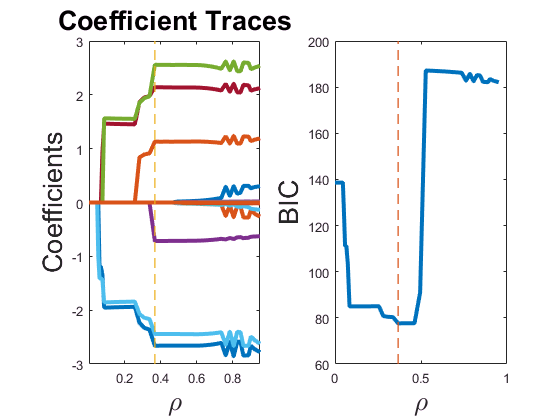

figure
subplot(1,2,1),vbvs_plot(model), subplot(1,2,2),vbvs_plot(model,'bic')

4. Compare with traditional logistic regression.

% Train logistic regression
y(y==-1) = 0;
[B,dev,stats] = mnrfit(X, categorical(y));
% Generate test set
Xtest = mvnrnd(zeros(p,1),eye(p),1000);
ytest = random('bino', 1, logsig(Xtest*beta));
% Make prediction
y_vbvs = vbvs_logit_pred(Xtest, model);
y_logit = mnrval(B,Xtest); y_logit = y_logit(:,2);
display(['Accuracy of sparse model is ',num2str(sum(y_vbvs>0.5 == ytest)/1000)])

Accuracy of sparse model is 0.862


display(['Accuracy of generalized linear model is ',num2str(sum(y_logit>0.5 == ytest)/1000)])

Accuracy of generalized linear model is 0.797
